# Data generation experiment

### Overview

### Simulation Steps

### Uncertainty Quantification

### Trajectories

## load main workspace 

% load the workspace necessities
addpath(genpath(pwd));
load_db_params;

% load UAV airframe
uav_sern = 'X001';
conn = database(datasource_name, user_name, password);
octomodel = get_airframe(conn, uav_sern);

% load battery
battery_sern = 'B001';
battery = get_battery(conn, battery_sern);

% load motors
[Motor1, Motor2, Motor3, Motor4, Motor5, Motor6, Motor7, Motor8] = get_motors(conn, octomodel.id);

% get the current mission number
mission_id = table2array(select(conn, 'select id from mission_tb mt order by id desc limit 1;'));
if isempty(mission_id)
    mission_id = 1;
else
    mission_id = mission_id + 1;
end

% close the connection after loading the components, other fuctions handle data writing 
conn.close();

% load base directory
load_base_workspace;

% not used, need to update table schema but its fine for now dont delete
rul_hat = -1.0;

% initial flight time 
rft_hat = 18.0;

% position error threshold
avg_pos_err_thresh = 2.25;

% battery state of health threshold
battery_soh_thresh = .5 * battery.Q;

pos_err_threshold = 6.5;
min_soc = .3;



## Initialize some variables

end_sim_count = 0;

% number of stochastic simulations per mission index
n_samples = 1;

% for poly fitting this is the window size
lookback = 8;
horizon = 1;

% number of missions (can be oversized)
n_missions = 150;

% use variance from the datasets (find in other file) motor is artificial
r_std = .0003;
q_std = .65;
m_std = .0005;

% start @ factory levels with some variation
battery.R0 = max(abs(normrnd(rdeg(1), r_std)), .0001);
battery.Q = min(abs(normrnd(qdeg(1), q_std)), 15.5);
Motor2.Req = max(abs(normrnd(mdeg(1), m_std)), .001); 


## Main Simulation

####  just use the same trajectory

load_trajectory;
while trajectory.path_time > rft_hat
    load_trajectory;
end

for mission_idx = 1:n_missions
   
    sys = "TrueSystem";
    octomodel.sampletime = true_sample_rate;
    tic
    sim('truesystem.slx');
    toc
    
    distance = calculatedistance([pos_actual.Data(:,1) pos_actual.Data(:,2)]);
    conn = database(datasource_name, user_name, password);
    start = table2array(select(conn, 'select mt.dt_stop from mission_tb mt order by dt_stop desc limit 1;'));
    conn.close();
    if isempty(start)
        start = datetime(now, 'ConvertFrom', 'datenum');
    end
    start = datetime(start, 'InputFormat', 'yyyy-MM-dd HH:mm:ss');
    start = dateshift(start, 'start', 'second');
    start = start + minutes(1);
    stop = start + seconds(flight_time.Data(end, 1)*60);
    
    fprintf("[INFO] i: %d\tmission_id: %d\trul_hat: %.2f\tflight_time: %.2f\tdistance: %.2f\tR0: %.5f\tQ: %.2f\tReq: %.5f", mission_idx, mission_id, rft_hat, flight_time.Data(end, 1), distance, battery.R0, battery.Q, Motor2.Req)
    
    write_mission_data;
    

Elapsed time is 284.498966 seconds.


[INFO] i: 1	mission_id: 2347	rul_hat: 18.00	flight_time: 17.84	distance: 1302.03	R0: 0.02339	Q: 12.11	Req: 0.30387

[INFO] degradation parameters: 0.0014	15.2763	0.2372

###          calculate the degradation rate of change

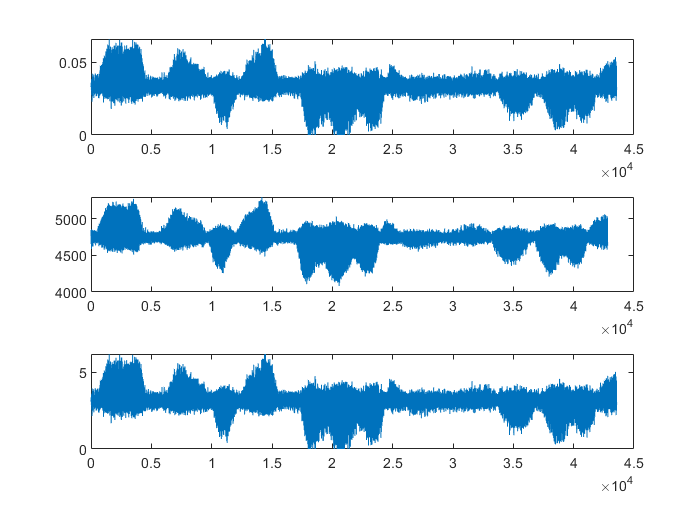

    if mission_idx > lookback
        % get the index numbers
        x = double(((mission_idx - (lookback)):1:mission_idx-1)');
        % sample the distribution at those index numbers
        r_ = r_deg_dist(x,2).*randn(lookback,1)+r_deg_dist(x,1);
        % fit a polynomial, the first result is the slope (rate of
        % change)
        r_poly = polyfit(x, smoothdata(r_, 'rlowess', 5), 1);
        

        q_ = q_deg_dist(x,2).*randn(lookback,1)+q_deg_dist(x,1);
        q_poly = polyfit(x, smoothdata(q_, 'rlowess', 5), 1);
        
        m_ = m_deg_dist(x,2).*randn(lookback,1)+m_deg_dist(x,1);
        m_poly = polyfit(x, smoothdata(m_, 'rlowess', 5), 1);

    end
 
    write_degradation_data;
    %%%clear('trajectory', 'battery_actual', 'battery_observed', 'ctrl_err', 'current', 'current_rs', 'euclidean_pos_err', 'flight_time', 'motors', 'pos_observed', 'pos_actual', 'stop_code' );    

### **         resample the degradation parameters for the next mission**

    battery.R0 = max(abs(normrnd(rdeg(mission_idx), r_std)), .0001);
    battery.Q = min(abs(normrnd(qdeg(mission_idx), q_std)), 15.5);
    Motor2.Req = max(abs(normrnd(mdeg(mission_idx), m_std)), .001);  
    fprintf("[INFO] degradation parameters: %.4f\t%.4f\t%.4f", battery.R0, battery.Q, Motor2.Req)  
   
    mission_id = mission_id + 1;
    

###         Stop conditions

    avg_pos_err = mean(euclidean_pos_err.Data(:,1));
    z_end = battery_actual.Data(end, 2);
    stop_code_res = max(find(any(stop_code.Data(:,:))));
    
    % update the end simulation count to know when to stop
    if stop_code_res ~= 3
        end_sim_count = end_sim_count + 1;
        fprintf("[WARN] end sim count incremented to: %d", end_sim_count)
        if end_sim_count == 10
            break;
        end
        if avg_pos_err > avg_pos_err_thresh
            disp('avg position error exceeded.')
        end
        if battery.Q < battery_soh_thresh
            disp('battery soh threshold exceeded.')
        end
        if z_end < min_soc
            disp('ending soc threshold violated')
        end
        
    end
        
    
end % end of all missions


f1 = figure(1); clf;
subplot(3,1,1);
plot(motor2_electric_torque.Data(:,1));

subplot(3,1,2);
plot(motor2_rpm.Data(:,1));

subplot(3,1,3);
plot(motor2_current.Data(:,1));